# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 11:26

## Create the Layer Graph

Create the layer graph variable to contain the network's layers.

lgraph = layerGraph();

## Add the Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    sequenceInputLayer([32 32 3],"Name","sequence","Normalization","zerocenter")
    sequenceFoldingLayer("Name","seqfold")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","maxpool_1")
    convolution2dLayer([5 5],32,"Name","conv_1")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([2 2],"Name","maxpool_2")
    convolution2dLayer([5 5],64,"Name","conv_2")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    sequenceUnfoldingLayer("Name","sequnfold")
    flattenLayer("Name","flatten")
    fullyConnectedLayer(4096,"Name","fc1")
    fullyConnectedLayer(1024,"Name","fc2")
    dropoutLayer(0.4,"Name","dropout")
    fullyConnectedLayer(50,"Name","fc3")
    fullyConnectedLayer(40,"Name","fc4")
    fullyConnectedLayer(5,"Name","fc5")
    fullyConnectedLayer(1,"Name","fc6")
    regressionLayer("Name","regressionoutput")];
lgraph = addLayers(lgraph,tempLayers);

## Connect the Layer Branches

Connect all the branches of the network to create the network's graph.

lgraph = connectLayers(lgraph,"seqfold/out","maxpool_1");
lgraph = connectLayers(lgraph,"seqfold/miniBatchSize","sequnfold/miniBatchSize");
lgraph = connectLayers(lgraph,"relu_2","sequnfold/in");

## Clean Up Helper Variable

clear tempLayers;

## Plot the Layers

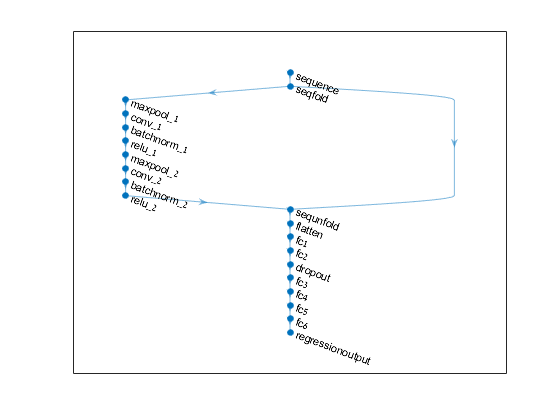

plot(lgraph);